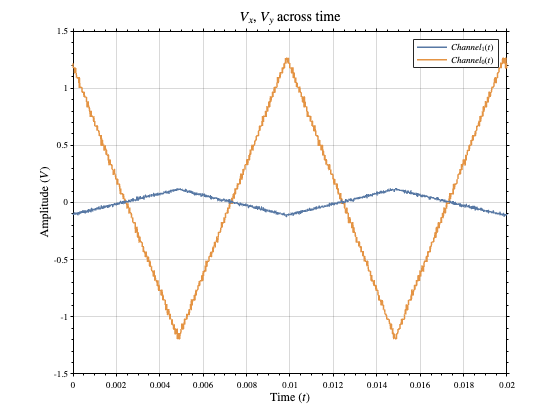

%%%% Author: Anson Li
%%%% Email: ting.h.li@mail.mcgill.ca
close all; clf; clc; cla;
working_directory = './part-1/';
input_csv_filename = '1-TRIANGLE-100-OHMS-WAVE.csv';

SignalName = '$100\Omega$ Resistor ';
PlotTitle = strcat('Part 1:  ',SignalName);
bandlimit = 500;


% output directory
out_directory = 'out/';
if ~exist(strcat(working_directory,out_directory),'dir')
    mkdir(strcat(working_directory,out_directory))
end
imageResolution = 600;

% output file name computations
output_pdf_filename = [input_csv_filename(1:end - 4), '.pdf'];
output_png_filename = [input_csv_filename(1:end-4),'-plotted.png'];

% Load Data from CSV
InputData = readmatrix(strcat(working_directory,input_csv_filename));

% Oscilloscope Timestep
sampling_interval = 8 * 10^(-6); % seconds

% time vector
dataLength=size(InputData,1);
t = 0:sampling_interval:(dataLength-1)*sampling_interval;

% grab the channels 
% REMARK: Correspondence of Channels
% Green channel on osc. is channel0 here,
% while the blue channel on osc. is channel1
channel0 = InputData(:, 4); channel1 = InputData(:,8);

% OSCILLOSCOPE PLOT of the two channels
% Plotting the osc. in matlab

%%%%%
%%%%%
%%%%

figure(1);
tiled1=tiledlayout('flow');
nexttile;
hold on;
plot(t, channel0, 'DisplayName', '${Channel}_0(t)$');
plot(t, channel1, 'DisplayName', '${Channel}_1(t)$');
title(['$V_x$, $V_y$', ' across time'], 'interpreter', 'latex');
legend('Interpreter', 'latex');

xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($V$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf, 'small');
hold off;


%%%%%
%%%%%
%%%%%



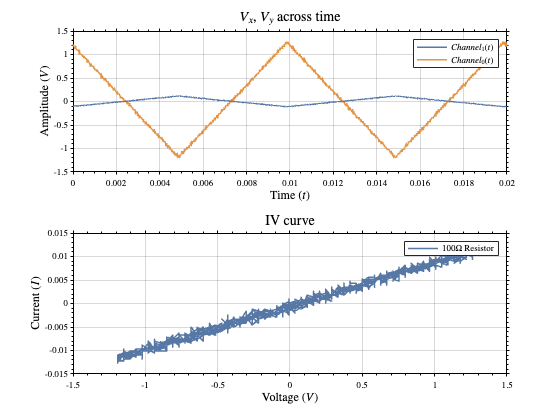

% Divide by negative 10 Ohms to obtain the current


% sometimes we want to do calculations with the channels, so we plot
% signal0, 1 instead of channel 0,1

signal0=channel0; 
signal1 = channel1./(-10);

% % signal1 is the current, see above

%%%%%
%%%%%
%%%%%
% Plot the iv curve
nexttile;
hold on;
plot(signal0,signal1,'DisplayName', SignalName);
title(['IV curve'], 'interpreter', 'latex');
legend('Interpreter','latex');

xlabel('Voltage ($V$)', 'Interpreter', 'latex');
ylabel('Current ($I$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');
hold off;

%%%%%
%%%%%
%%%%%

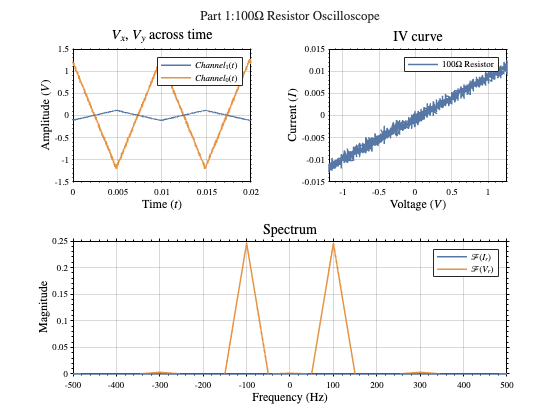

%%% SPECTRUM CALCULATIONS
% Frequency and Period of Channel 0?
% see SIG_INFO.m in MATLAB_DEFAULTS for how the following function is
% defined.
[rms0,bfreq0,pVector0,fVector0]=SIG_INFO(signal0,sampling_interval);
[rms1,bfreq1,pVector1,fVector1]=SIG_INFO(signal1,sampling_interval);

% range of the spectrum is 1/sampling_interval / 2 = [-62.5k, +62.5k]
% spectrum filename
combined_output_pdf_filename = [input_csv_filename(1:end-4), '-COMBINED-OSC.pdf'];
combined_output_png_filename = [input_csv_filename(1:end-4), '-COMBINED-OSC-plotted.png'];

%%%%%
%%%%%
%%%%%
% Plot Spectrum over [-bandlimit, +bandlimit]
nexttile([1, 2]);
hold on;
plot(fVector0,pVector0,'DisplayName','$\mathcal{F}(V_r)$');
plot(fVector1,pVector1,'DisplayName','$\mathcal{F}(I_r)$');
legend('Interpreter','latex');

xlim([-bandlimit,+bandlimit]); % lock frequency range

title(['Spectrum'], 'interpreter', 'latex');
xlabel('Frequency (Hz)', 'Interpreter', 'latex');
ylabel('Magnitude', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');
hold off;
title(tiled1, [PlotTitle, ' Oscilloscope'], 'Interpreter', 'latex');
print(gcf, strcat(working_directory,out_directory,combined_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,combined_output_png_filename),'Resolution',imageResolution);

%%%%%
%%%%%
%%%%%

% use LPF to clean up the plots and IV curve
% try apply LPF, minimum of 5kHz 
signal2=lowpass(signal0,min(bandlimit*4, 5000), 1/sampling_interval);
signal3=lowpass(signal1,min(bandlimit*4, 5000), 1/sampling_interval);

% LPF filenames
combined_lpf_output_pdf_filename = [input_csv_filename(1:end-4), '-COMBINED-LPF.pdf'];
combined_lpf_output_png_filename = [input_csv_filename(1:end-4), '-COMBINED-LPF-plotted.png'];

% plot lpf
figure(2);
tiled2=tiledlayout('flow');
nexttile;
hold on;
plot(t, signal2, 'DisplayName', '$v(t)$');
title(['Voltage'], 'interpreter', 'latex');
legend('Interpreter', 'latex');
xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($V$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf, 'small');
hold off;

%%%%%
%%%%%
%%%%%

nexttile();
hold on ;
plot(t, signal3, 'DisplayName', '$i(t)$');
title(['Current'], 'interpreter', 'latex');
legend('Interpreter', 'latex');

xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($A$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf, 'small');
hold off;


%%%%%
%%%%%
%%%%%

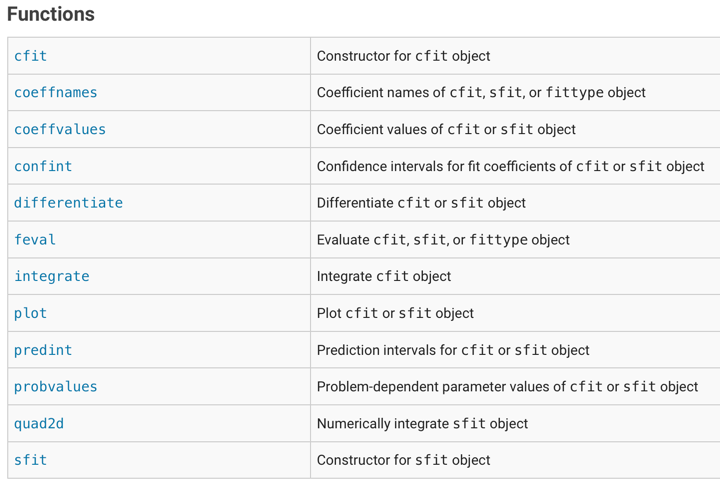

LinFitIV = fit(signal2,signal3,'poly1') % linear fit param, for exp. fit try 'exp1'

LinFitIV =      Linear model Poly1:
     LinFitIV(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.009284  (0.009273, 0.009295)
       p2 =  -0.0006083  (-0.0006159, -0.0006007)

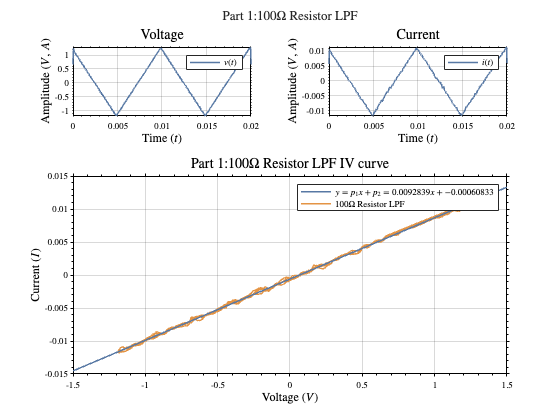

nexttile([2 2]);
hold on;
plot(signal2,signal3);
plot(LinFitIV);
LinFitLabel = [num2str(LinFitIV.p1),'x + ',num2str(LinFitIV.p2)];
title([PlotTitle,' LPF IV curve'], 'interpreter', 'latex');

legend([SignalName, ' LPF'], ...
    ['$y=p_1x + p_2=',LinFitLabel,'$'], ...
    'interpreter','latex');

xlabel('Voltage ($V$)', 'Interpreter', 'latex');
ylabel('Current ($I$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');
hold off;
title(tiled2, [PlotTitle, ' LPF'], 'Interpreter', 'latex')

print(gcf, strcat(working_directory,out_directory,combined_lpf_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,combined_lpf_output_png_filename),'Resolution',imageResolution);

Fitting for anonymous functions

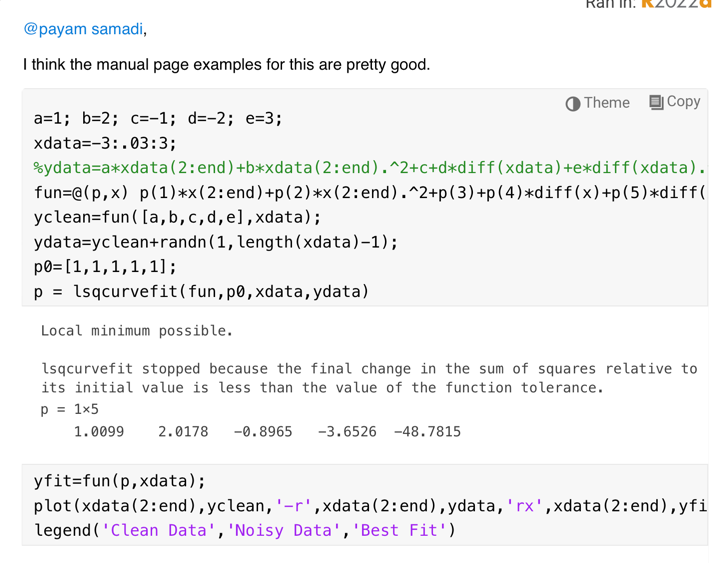

% if fit to piecewise linear, use  Diodefitter
DiodeFitter = @(p,x) max(p(1)*(x - p(2)),0);